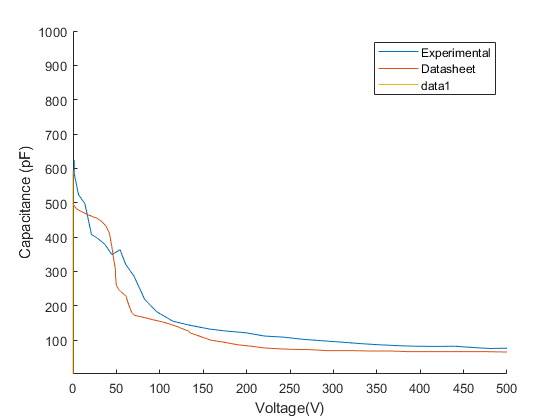

plot(timeFit,VdsFit)

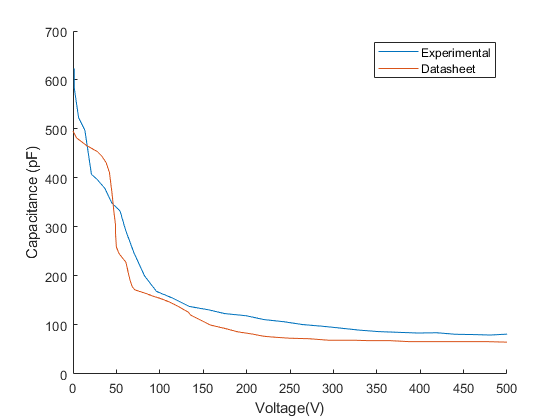

L = 150e-6;
[MatrixSize,~] = size(VdsFit);
Int = customintegral(timeFit,VdsFit);
C = (1:MatrixSize)*0;
for i=1:MatrixSize-1
   dummyV = VdsFit(i) - VdsDeriv;
   [~,ix] = min(abs(dummyV));
   if VdsFit(i)<50
       DerivMean = movmean(Deriv,7);
    else
       DerivMean = movmean(Deriv,5);
    end
   C(i) = (Int(MatrixSize) - Int(i))/(L*DerivMean(ix))/1e-12;
end
figure
hold all
plot(VdsFit,C)
plot(VdsDS,CossDS)
ylabel('Capacitance (pF)');xlabel('Voltage(V)');
legend('Experimental','Datasheet')
xlim([0 500])
hold off

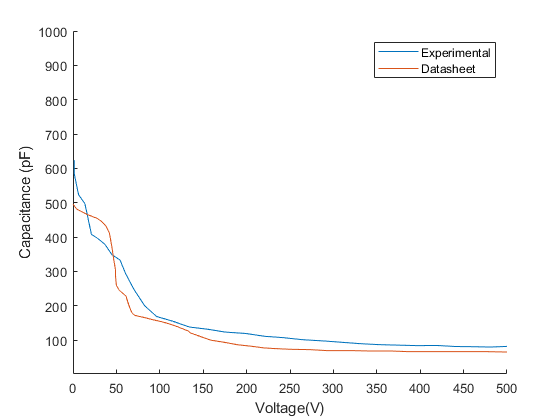

figure
hold all
semilogy(VdsFit,C)
semilogy(VdsDS,CossDS)
ylabel('Capacitance (pF)');xlabel('Voltage(V)')
legend('Experimental','Datasheet')
ylim([1 1000])
xlim([0 500])

function [integral] = customintegral(respect_to,inputwave)
%Calculates the inputwave's integral with respect to 'respec_to' waveform.

for i=1:1:length(respect_to)
    for j=1:1:i
    dummyinputwave(j)= inputwave(j);
    dummyrespect_to(j) = respect_to(j);
    end
    dummyinputwave_dt = dummyinputwave.*gradient(dummyrespect_to);
    inputwave_int(i) = trapz(dummyinputwave_dt);
end
integral = inputwave_int';
end